# MAE 207 HW1: RK2 and RK4 Implementation

Albert Wen

Department of Mechanical and Aerospace Engineering

October 13, 2022

This is main Live Script that should be run for my own implementation. There will be no `input` invocations, unlike what is shown in the example code of Numerical Renaissance. However, the general parameters from the examples will be used.

Also, I will not include a target accuracy because I'm not quite sure how to implement it.

clear; clc;

## Time Interval and Time Step Size

T = 100; % max time run
h = 0.01;   % time step size

### Lorenz Equation

x0 = [1, 1, .01];
LorR = 'L';

#### RK2 Simulation

RKtype = 2;
posLorenz2 = runEq(LorR, T, h, RKtype, x0);

#### RK4 Simulation

RKtype = 4;
posLorenz4 = runEq(LorR, T, h, RKtype, x0);

### Rossler Equation

x0 = [3, 3, .1];
LorR = 'R';

#### RK2 Simulation

RKtype = 2; 
posRossler2 = runEq(LorR, T, h, RKtype, x0);

#### RK4 Simulation

RKtype = 4;
posRossler4 = runEq(LorR, T, h, RKtype, x0);

## Plotting

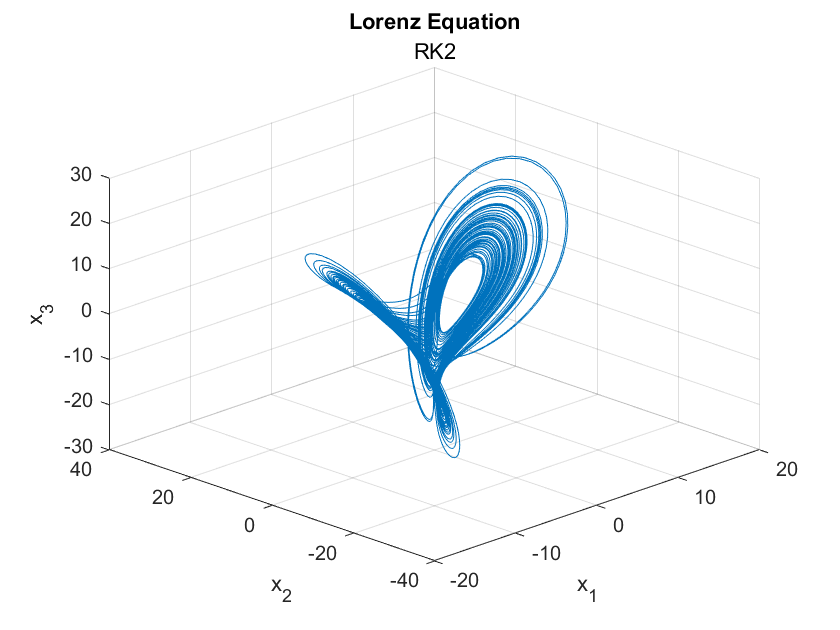

title_L = 'Lorenz Equation';
fig_L2 = plotSim(posLorenz2, title_L, "RK2");
saveas(fig_L2, 'Lorenz2.png');
saveas(fig_L2, 'Lorenz2.eps');

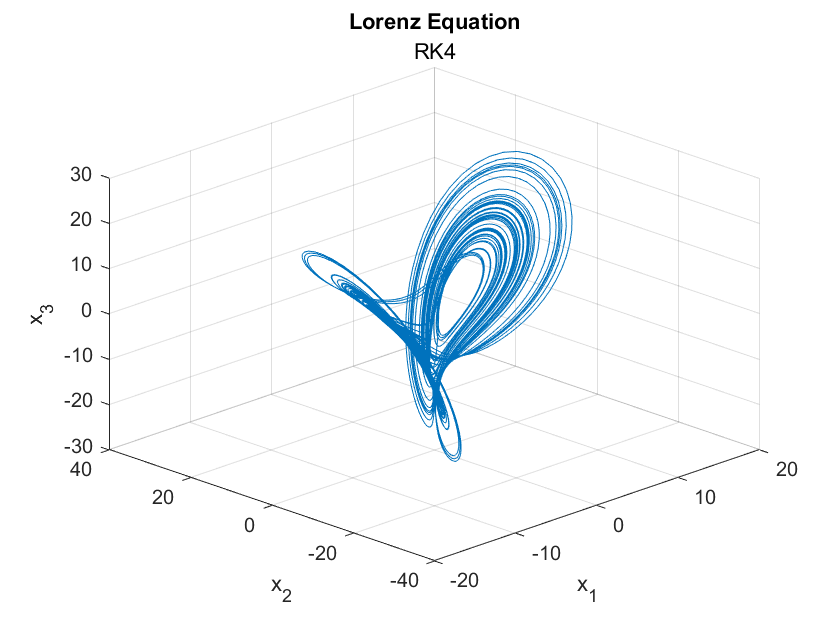

fig_L4 = plotSim(posLorenz4, title_L, "RK4");
saveas(fig_L4, 'Lorenz4.png');
saveas(fig_L4, 'Lorenz4.eps');

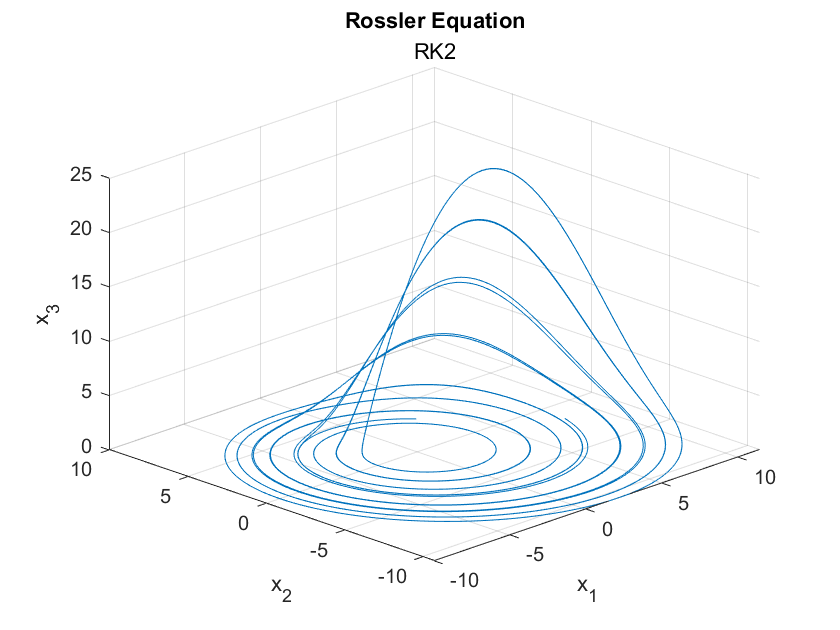

title_R = 'Rossler Equation';
fig_R2 = plotSim(posRossler2, title_R, "RK2");
saveas(fig_R2, 'Rossler2.png');
saveas(fig_R2, 'Rossler2.eps');

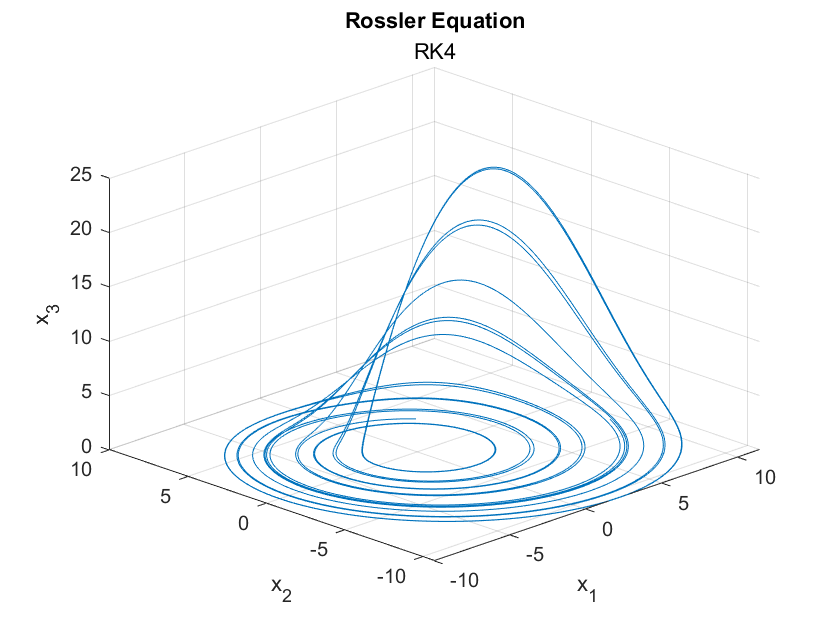

fig_R4 = plotSim(posRossler4, title_R, "RK4");
saveas(fig_R4, 'Rossler4.png');
saveas(fig_R4, 'Rossler4.eps');

% exportfig(fig_L2, 'Lorenz2.eps', 'bounds', 'tight'); % OCTAVE?
% exportfig(fig_L4, 'Lorenz4.eps', 'bounds', 'tight');
% exportfig(fig_R2, 'Rossler2.eps', 'bounds', 'tight');
% exportfig(fig_R4, 'Rossler4.eps', 'bounds', 'tight');